syms V T
R = 8.314;
Ttriple = 180.97;
Tcrit = 437.22;
Pcrit = 5.34e+6;
antA = 4.29371;
antB = 995.445;
antC = -47.869;
Pant = @(T) (10^5)*10^(antA - (antB/(T + antC)));
Ptriple = Pant(Ttriple)

Ptriple = 65.2891


syms T V
omega = -1 - log10(Pant(0.7*Tcrit)/Pcrit)

omega = 0.2894

k_small = 0.37464 + 1.5422*omega - 0.26992*omega^2

k_small = 0.7983

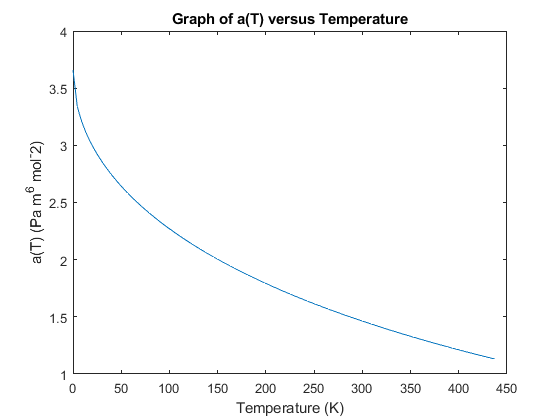

alpha_T = @(T) (1 + k_small*(1 - sqrt(T./Tcrit)))^2;
a_T = @(T) (0.45724*(R^2)*(Tcrit^2)/Pcrit) * alpha_T(T);

Trange_a = linspace(0,Tcrit,100);
a_array = [];
for i = 1:length(Trange_a)
    val = a_T(Trange_a(i));
    a_array(i) = val;
end

plot(Trange_a,a_array)
xlabel('Temperature (K)')
ylabel('a(T) (Pa m^6 mol^-2)')
title('Graph of a(T) versus Temperature')


b = 0.0778*R*Tcrit/Pcrit

b = 5.2960e-05

Prb = @(T,V) R*T./(V - b) - a_T(T)/(V.*(V + b) + b*(V - b));
Vcrit = vpasolve(Prb(Tcrit,V) == Pcrit,V,[0 Inf]);
acentric = omega

acentric = 0.2894

Zc = Pcrit*Vcrit/(R*Tcrit)

$$Zc = 0.32137902517362299583112149146058$$

% FOR REPORT PURPOSES

% CLAUSIUS CLAPEYRON EQUATION
C = log(Pcrit) + (33.78e+3)/(R*Tcrit)

C = 24.7836

P_unknown = exp(C - (26.4e+3)/(R*(6.88+273.15)))

P_unknown = 6.8984e+05

P_norm = exp(C - (25.05e+3)/(R*(298)))/10^5

P_norm = 23.5699


Vtriple = vpasolve(Prb(Ttriple,V) == Ptriple,V,[0 Inf])

$$Vtriple = \left(\begin{array}{c} 0.000058439093699858376088569892642255\\ 0.0010768312347662229233814142818168\\ 23.04377590345457740154810921613 \end{array}\right)$$

Vcrit = vpasolve(Prb(Tcrit,V) == Pcrit,V,[0 Inf])

$$Vcrit = 0.00021876926723419941075559892693863$$

Vnormal = vpasolve(Prb(180.15,V) == 1*10^5,V,[0 Inf])

$$Vnormal = \left(\begin{array}{c} 0.000058394457967533670093261143113736\\ 0.0011876001388701740596590065193095\\ 0.013678716353944315019449003770783 \end{array}\right)$$